## SimpleUSBCameraTutorial.mlx is a template for future Fun-Robo USB Camera Code 

This is a simple color object tracking USB Camera Tutorial for your robots. 

*This example shows how to use the snapshot function to acquire live images from USB webcams. To use it you need to first load: *

***MATLAB Support Package for USB Webcams ****which provides the ability to bring *

*live images from any USB video class (UVC) compliant webcam into MATLAB. *

*Available USB webcam functions: *

- *webcamlist       - List of webams connected to your system *

- *webcam           - Connection to a webcam *

- *preview            - Preview live video data from webcam *

- *closePreview   - Close webcam preview window *

*Jessica Brown 2/14/2022 Revision 1*

clc                      % clear command window
clear                    % clear MATLAB workspace
imaqreset                % clear all image objects from memory

**Set up robot control system **( code that runs once ) 

% Indentifying Available Webcams, The webcamlist function provides a cell
% array of all webcams on the current system that MATLAB can access.
% webcan(2) is hopefully {'Microsoft LifeCam Cinema'}, if not change code
% below

camList = webcamlist

camList = 2×1 cell array
    {'Integrated Webcam'            }
    {'Microsoft® LifeCam Cinema(TM)'}


% Set up Connection to the USB Webcam, print its properties 
robotCam = webcam(2)

robotCam =   webcam with properties:

                     Name: 'Microsoft® LifeCam Cinema(TM)'
     AvailableResolutions: {'640x480'  '640x360'  '424x240'  '352x288'  '320x240'  '176x144'  '160x120'  '1280x720'  '960x544'  '800x448'  '800x600'}
               Resolution: '640x480'
                    Focus: 9
                FocusMode: 'auto'
                 Contrast: 5
                      Pan: 0
                     Zoom: 0
                Sharpness: 25
             ExposureMode: 'manual'
         WhiteBalanceMode: 'manual'
               Saturation: 83
             WhiteBalance: 4500
                 Exposure: -8
                     Tilt: 0
    BacklightCompensation: 0
               Brightness: 100


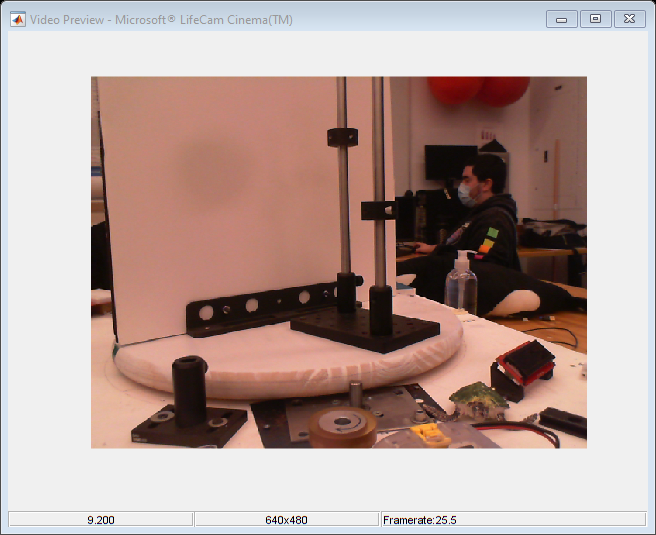

% Fix auto exposure problem, set it to manual, set exposure to work in lab lighting 
% set witebalance to manual, too. Auto exposure and white balance drive 
% computer vision algorithms crazy by constantly changing
SETUPUSBCAMERA(robotCam);

% Preview Video Stream
preview(robotCam)

% wave hand in front of lens to make sure camera is working
%gCamTest = input('move hand in front of camera, type G, then hit Enter ', 's');
%clc;

% close Preview window
%closePreview(robotCam);

r = rateControl(0.1); % create a 0.1 hz loop rate
reset(r) % reset loop time to zero

**Run robot control loop **( code that runs over and over ) 

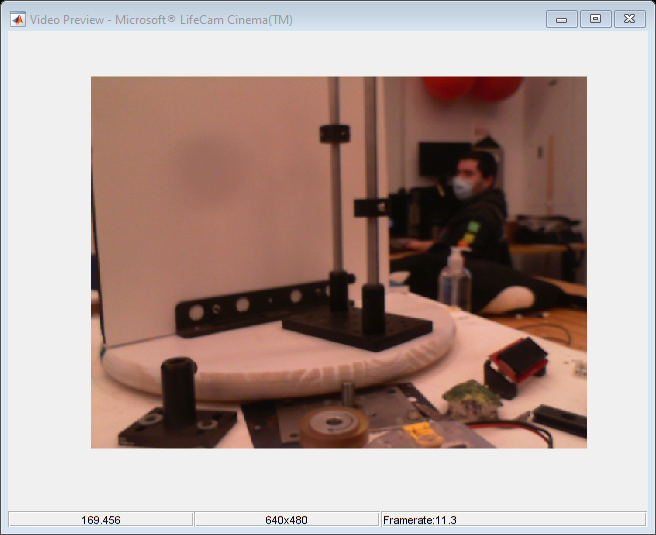

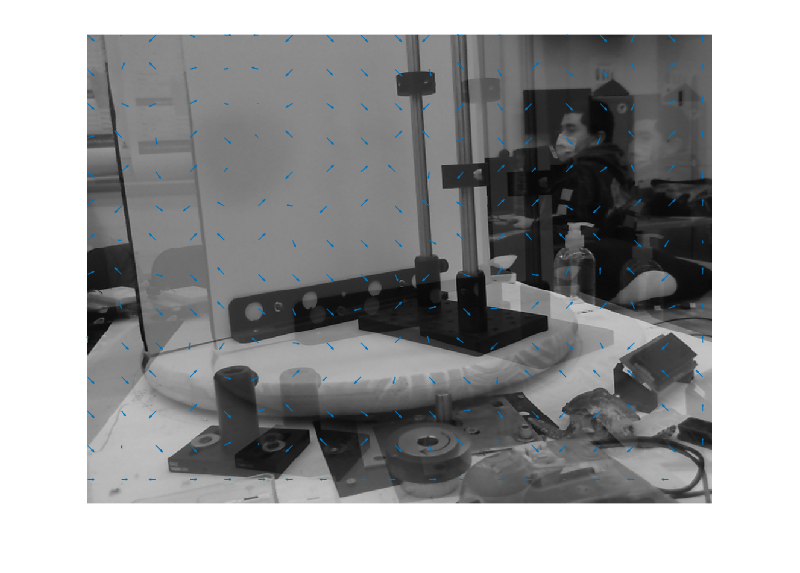

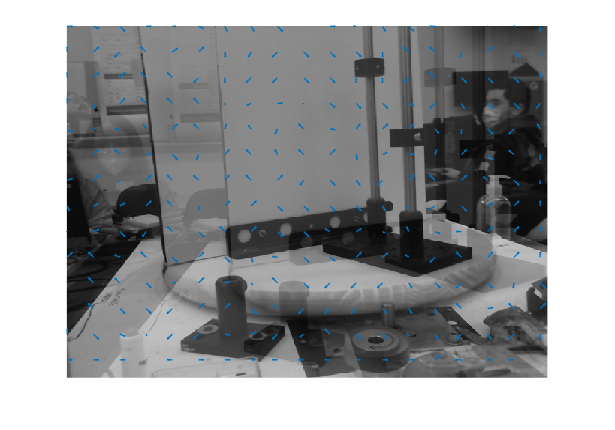

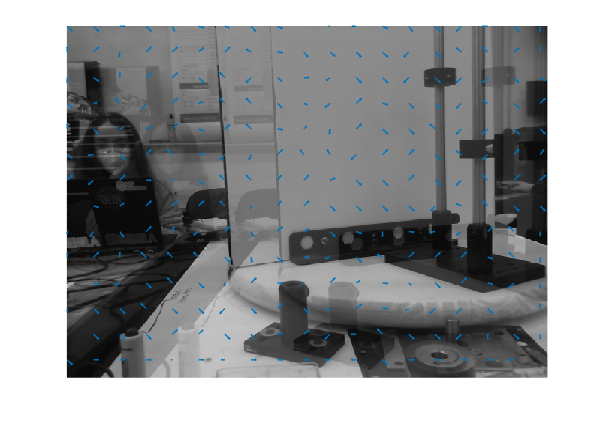

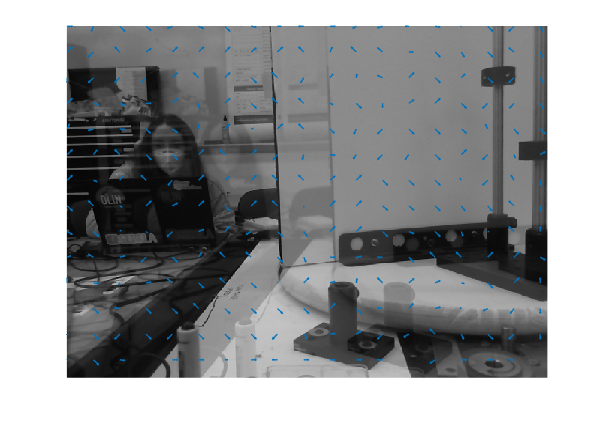

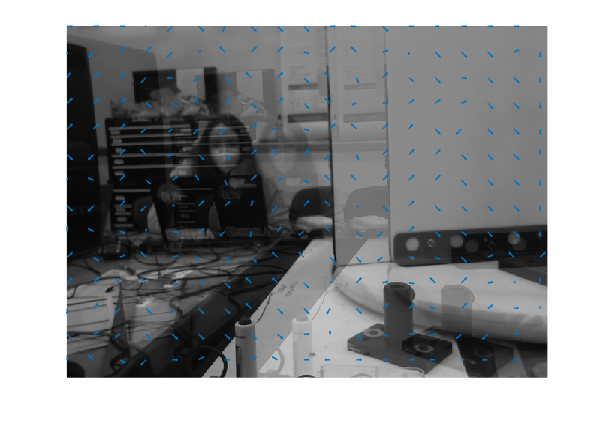

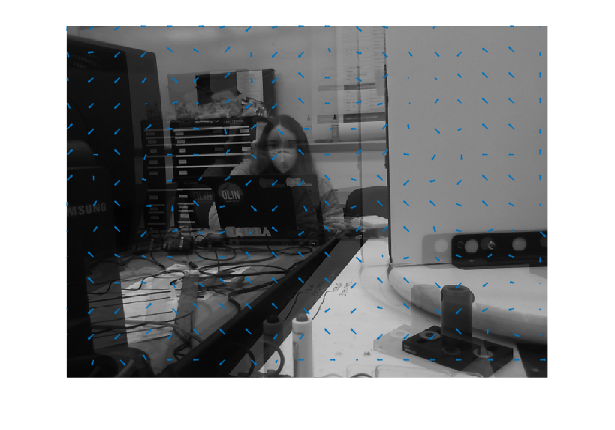

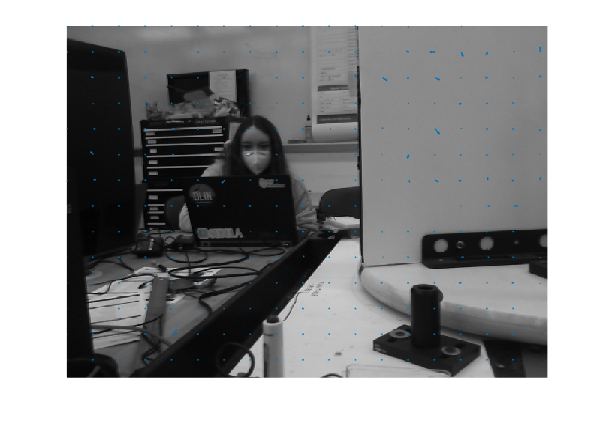

controlFlag = 1; % create a loop control 
initialFrame = im2double(im2gray(snapshot(robotCam)));
nTests = 10;
while (controlFlag < nTests + 1) % loop till ntests data captured

    robotIMG = im2double(im2gray(snapshot(robotCam))); % take snapshot convert to grayscale
    blkMatcher = vision.BlockMatcher('ReferenceFrameSource', ...
        'Input port', 'BlockSize',[35 35]);
    blkMatcher.OutputValue = 'Horizontal and vertical components in complex form';
    alphaBlend = vision.AlphaBlender; 
    motion = blkMatcher(initialFrame, robotIMG);
    img12 = alphaBlend(robotIMG,initialFrame);
    [X,Y] = meshgrid(1:35:size(robotIMG,2),1:35:size(robotIMG,1));
    figure(controlFlag);
    imshow(img12)
    hold on 
    quiver(X(:),Y(:),real(motion(:)),imag(motion(:)),0)
    hold off
    savefig('test.fig');

    % figure(camWindow) % go to camwindow to show new image 
    %image(robotIMG) % show image in camwindow figure 

    initialFrame = robotIMG;
    
    %waitfor(r); % wait for control loop cycle to complete
    controlFlag = controlFlag + 1; % increment loop 
end 

**Mission data processing **

For many robot applications, you will need to post-process the data collected after the mission. Here we will plot the measured versus actual range positions. 

% Add post processing code here, might be good to download Images to a
% MATLAB drive location where you can work on processing them later

**Clean shut down**

Finally, with most embedded robot controllers, it's good practice to put all actuators into a safe position and then release all control objects and shut down all communication paths. This keeps systems from jamming when yoou want to run again.  

% Stop program and clean up the connection to WebCam 
% when no longer needed 

clc 
clear robotCam            % connection is no longer needed, clear the cam variable. 
disp('SimpleUSBCameraTutorial Done')
beep % play system to let user know program is ended

**Robot Functions **(store this codes local functions here)

In practice for modularity, readability and longevity, your main robot code should be as brief as possible and the bulk of the work should be done by functions 

function CONTROL_LOOP_INPUT(time)
    disp('robot running, cntrl-c to stop')
    fprintf('The loop time is %d, \n',time);
end

**Sense Functions **(store all Sense related local functions here)

function [] = SETUPUSBCAMERA(robotCam)
    % SETUPUSBCAMERA creates and configures a Webcam to be a simple robot
    % vision system. It requires a standard Webcam attached to
    % your computer and takes webcam object name as sole input. 
    % You ned to set your cameras unique parameters to optimize picture 
    % J. Brown 2022 Rev 1

    % Fix auto exposure set it to manual, set whitebalance to manual too
    robotCam.ExposureMode = 'manual'; % for LifeCam
    robotCam.WhiteBalanceMode = 'manual';
    % experimentlaly determine best exposure setting for lab, enter here
    robotCam.Exposure = -8; % for LifeCam
    % robotCam.WhiteBalanceMode = 'manual'; % for LifeCam
    robotCam.Brightness = 100;
end 

function [robotImage] = SENSE(robotCam)
    % This function acquires a single image from the USBCamera testCam
    % and displays it in a stand alone figure 

    robotImage = snapshot(robotCam);
end 

**Think Functions **(store all Think related local functions here)

function THINK(time)
    % null function, not much thinking to do here
end 

**Act Functions **(store all Act related local functions here)

function ACT(time)
    % null function, not much thinking to do here
end 